clear
data = readtable('titanic\train.csv');
data1 = zeros(6,891)

data1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

for i = 1 : 891 
    if strcmp(data.Sex{i} ,'male')
        data1(1,i) = 1;
    else
        data1(1,i) = -1;
    end
end
data1(2,:) = data.Pclass';
data1(3,:) = data.Age';
data1(4,:) = data.SibSp';
data1(5,:) = data.Parch';
data1(6,:) = data.Fare';
for i = 1 : 6
    average(i) = nanmean(data1(i,:));
end
data1(isnan(data1)) = average(3);
average = average';
data1 = data1 - average * ones(1,891);
C = 1 / 891 * data1 * data1';

[V,D]=eig(C);
[~,inx] = sort(diag(D),'descend');
V_PCA = V(:,inx(1:2));
Y = V_PCA' * data1

Y =   -25.1508   39.2941  -24.3698   21.0408  -24.0206  -23.7487   20.2815  -11.8346  -21.1301   -2.5282  -16.1565   -4.9114  -24.4060   -0.6810  -24.7489  -15.5436   -3.7842  -19.1995  -14.1668  -24.9745   -6.0683  -19.0890  -24.5483    3.2574  -11.6734   -0.5872  -24.9815  230.4545  -24.3205  -24.3109   -4.2105  114.2888  -24.4497  -20.7658   49.9134   20.1141  -24.9773  -24.3803  -14.4973  -21.3592  -22.4572  -11.2614  -24.3109    8.7000  -24.5954  -24.1568  -16.7062  -24.4497  -10.5259  -14.7007
    7.0638   -7.2979    3.0783   -4.7677   -5.9262   -0.6193  -23.8204   27.4580    2.1869   15.6409   25.3196  -28.4524    9.0613   -9.2414   15.0665  -25.7081   27.6863   -0.5206   -1.6372   -0.6357   -5.4829   -4.8179   14.0718    1.7374   21.4782   -8.2241   -0.6510   16.6669   -0.6189   -0.6337  -10.4526    2.9300   -0.6222  -36.8555    2.9584  -11.8054   -0.6509    8.0621   11.3734   15.1750  -10.8488    2.4186   -0.6337   26.9528   10.0713   -0.6298   -0.4169   -0.6222   -0.2366   11

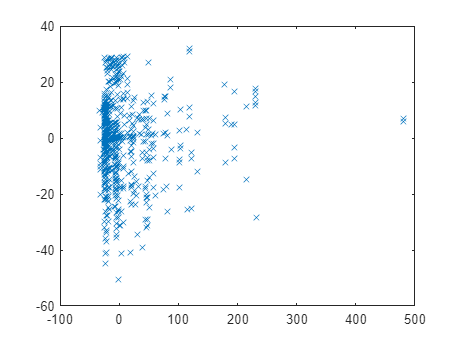


figure;
plot(Y(1,:),Y(2,:),'x');